## Extract all the topics of interest from ROSBAG

% requirements - 

ROS toolbox

Mapping toolbox

rosbagReader.m script in same location as this file

clc
clear
% Each bag can be passed directly and named after the experiment
% the output of custom rosbagReader function is to generate dataset of all
% topics and combine all the readings in entire rosbag under one header

flat_concrete = rosbagReader('fsc_v_0.2_m_0004_2023-05-06-14-50-57.bag');

bank_grass = rosbagReader('fsc_v_0.2_m_0002_2023-05-06-14-12-47.bag');

## **Plot example of Linear Acceleration in X with respect to relative time **

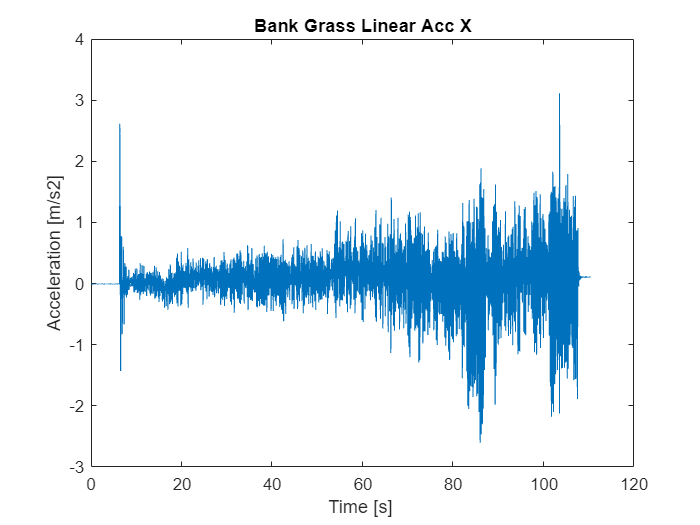

% Plotting each topic / any quantity becomes easier
ax = bank_grass.gx5_imu_data.LinearAcceleration.X;
% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = bank_grass.gx5_imu_data.RelTime;

fignum = 1;
figure(fignum)
plot(Reltime,ax)
title('Bank Grass Linear Acc X')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

## **Convert the GPS data to ENU-Carthesian coordinate frame**

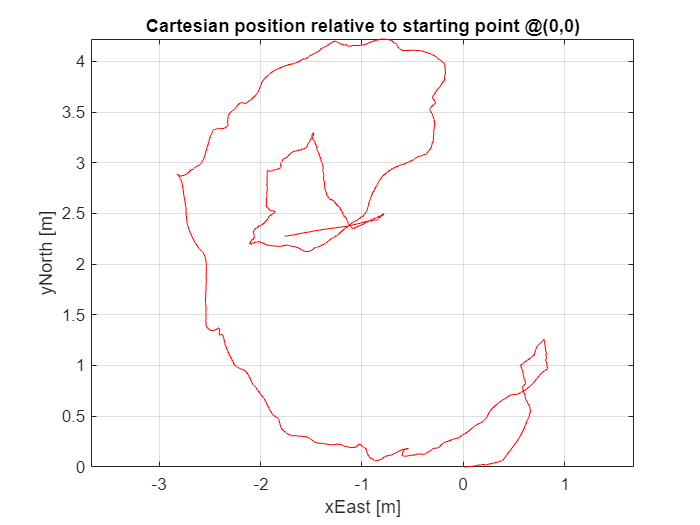

%Lets now plot navsatfix and coverted the quantities using geodetic to enu
%func and have a trajectory of robot

gpsLat = bank_grass.piksi_multi_position_navsatfix_best_fix.Latitude;
gpsLon = bank_grass.piksi_multi_position_navsatfix_best_fix.Longitude;
gpsAlt = bank_grass.piksi_multi_position_navsatfix_best_fix.Altitude;
gpsReltime = bank_grass.piksi_multi_position_navsatfix_best_fix.RelTime;
% Define the reference coordinates, corresponding to (0,0,0) coordinates
% let's pick the starting point of the trajectory according to the /bestfix
% topic
[xEastGPS, yNorthGPS, zUpGPS] = geodetic2enu(gpsLat ,gpsLon,gpsAlt,...
                                    gpsLat(1), gpsLon(1), gpsAlt(1),...
                                    wgs84Ellipsoid,"degrees");


fignum = 1;
figure(fignum)
plot(xEastGPS,yNorthGPS,'r');
grid on
axis equal
xlabel('xEast [m]');
ylabel('yNorth [m]');
title('Cartesian position relative to starting point @(0,0)');

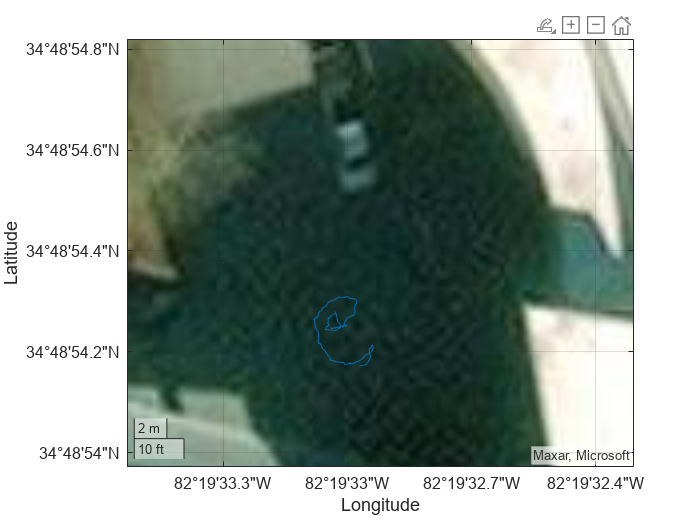

%% Lets see if the experiment area more clearly with satellite image
fignum = 1;
figure(fignum)
geoplot(gpsLat,gpsLon);
geobasemap satellite